## CONVOLVE THE CAT

## SECTION 1: Two-dimensional moving average

When we convolve an image with a kernel, we replace each pixel in the image with a weighted average of itself and surrounding pixels:

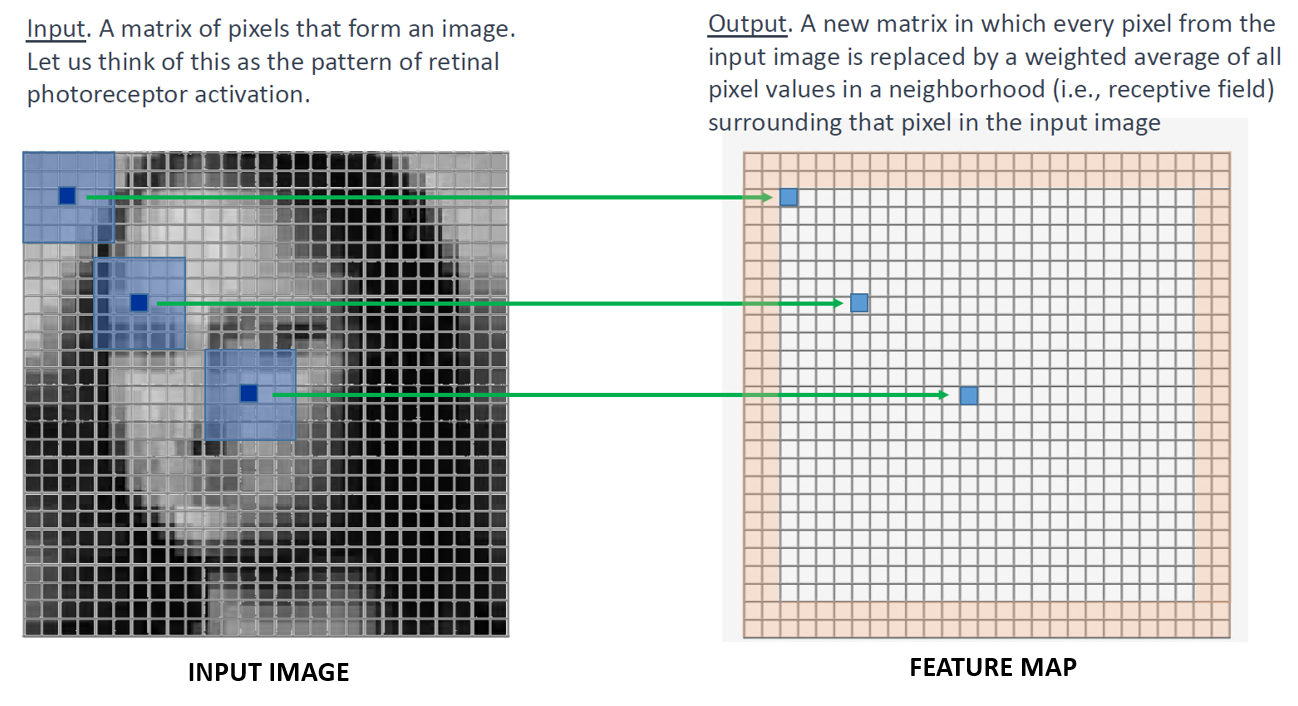  

The result of the convolution operation depends upon the SIZE of the kernel and the values we choose for the kernel weights. To demonstrfate this, let's concolve the following 100x100 pixel grayscale image of a cat with a variety of different kernels:

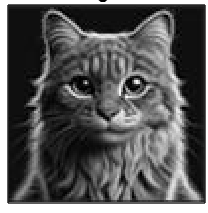

One of the simplest kernels is a BOXCAR KERNEL, defined as a square kernel that contains identical values for all the weights. We often require that the weight values in the kernel should sum to 1 (so that we do not change the overall brightness of the image when we convolve it with the kernel). Hence, if there are K weight values in the boxcar kernel, each weight will be equal to 1/K.

Let's convolve our cat image with 3 different boxcar kernels: a 3x3, a 5x5, and a 7x7.

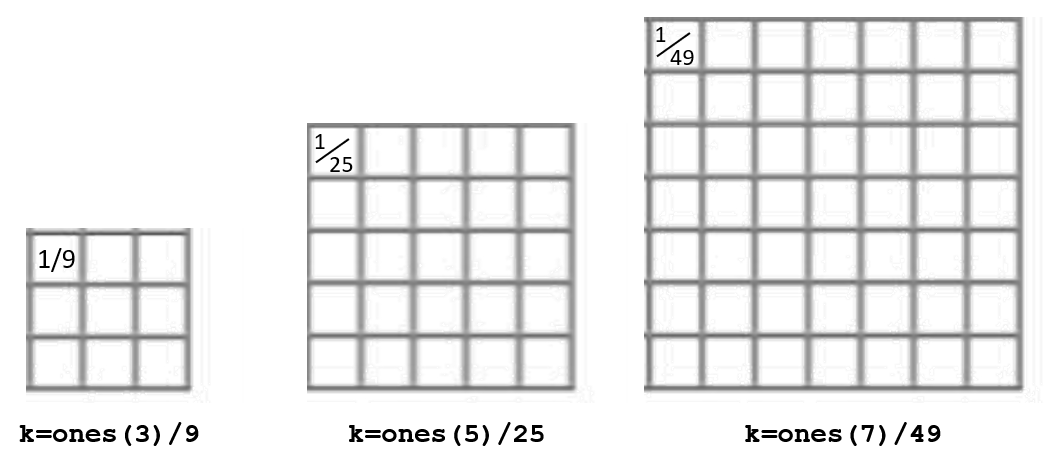

To perform the convolutions, execute the code below by clicking on 'Run Section' in the menu above:

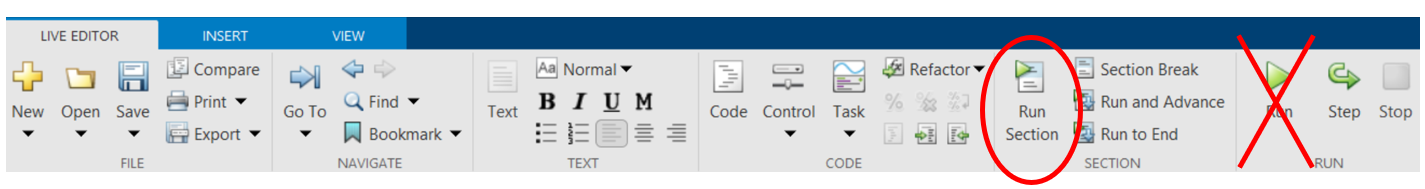

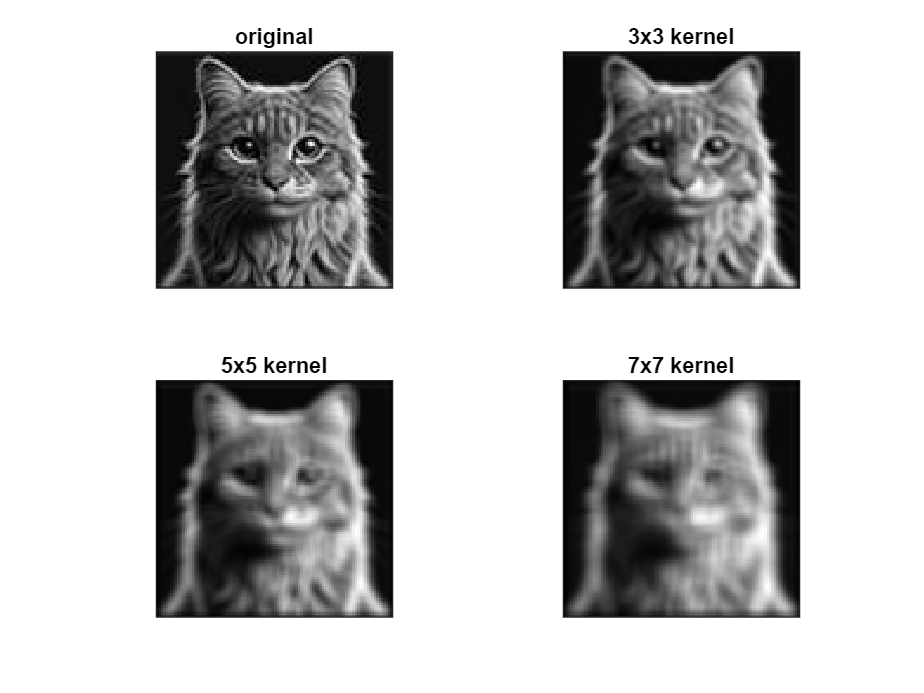

clear all; % clear all workspace variables

clf;

% set working directory to 'userpath' if it exists
if exist('C:\Users\ericy\OneDrive\Desktop\UCLA College stuffs\Senior Class\Winter\PSYCH 119D\MATLAB')
    workingfolder=[userpath '/Psych119D'];
else % otherwise use current directory
    workingfolder=pwd;
end

SIDfile; 

% load cat image
noblecat=imread('C:\Users\ericy\OneDrive\Desktop\UCLA College stuffs\Senior Class\Winter\PSYCH 119D\MATLAB/noblecat.jpg'); % swatting hand
noblecat=double(noblecat)/double(max(noblecat(:)));

%plot source image
subplot(2,2,1);
imagesc(noblecat);
axis square; colormap gray; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('original');

%convolve with 3x3 boxcar kernel
subplot(2,2,2);
k=ones(3)/9;
convcat3=conv2(double(noblecat),k,'same');
imagesc(convcat3);
axis square; colormap gray; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('3x3 kernel');

%convolve with 5x5 boxcar kernel
subplot(2,2,3);
k=ones(5)/25;
convcat5=conv2(double(noblecat),k,'same');
imagesc(convcat5);
axis square; colormap gray; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('5x5 kernel');

%convolve with 7x7 boxcar kernel
subplot(2,2,4);
k=ones(7)/49;
convcat7=conv2(double(noblecat),k,'same');
imagesc(convcat7);
axis square; colormap gray; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('7x7 kernel')

## QUESTION 1 

Select the statement below that best describes the results from sectoin 1 above:

answer.Q1=1

answer = struct with fields:
    Q1: 1


## SECTION 2: Impulse kernels

As we have just seen above, convolution with a boxcar kernel can perform smoothing (or blurring) operation on an image. There are MANY OTHER operations we can perform on an images by convolving them with different kinds of kernels! Convolution is a flexible and powerful tool for filtering images in different ways. 

A IMPULSE FUNCTION is kernel (of any size) that consists entriely of zeros except for a single entry equal to one (notice that an impulse kernel satisfies the constraint that its values sum to one). When the nonzero entry is in the center of the kernel (regardless of the kernel size), the output image is identical to the input image. You can verify this by hitting 'Run Section' to run the script below, which convolves the cat image with a 7x7 impulse kernel: 

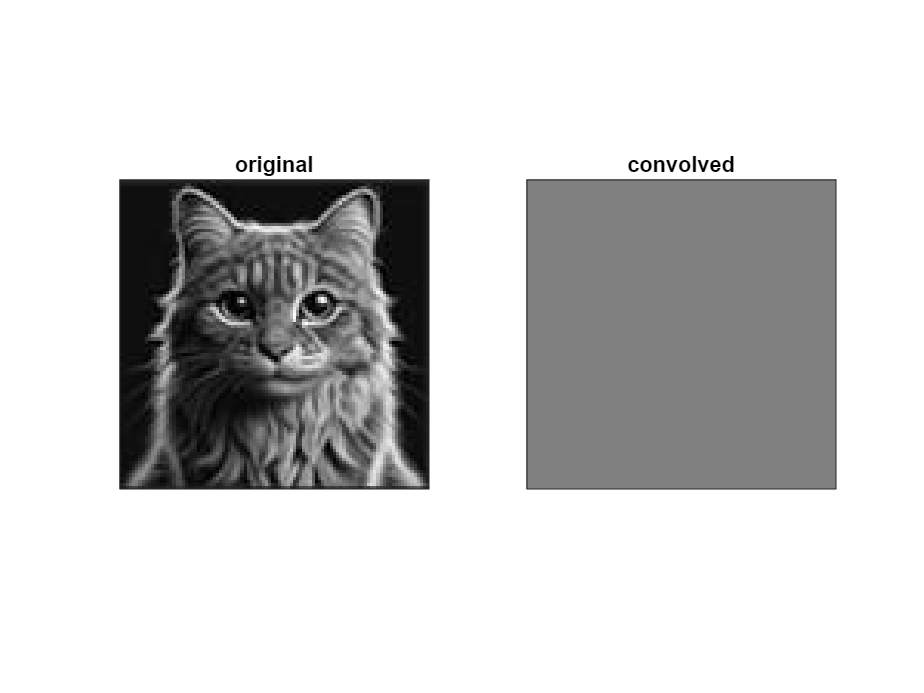

clf;

kernel=[0  0  0  0  0  0  0; ...
        0  0  0  0  0  0  0; ...
        0  0  0  0  0  0  0; ...
        0  0  0  0  0  0  0; ...
        0  0  0  0  0  0  0; ...
        0  0  0  0  0  0  0; ...
        0  0  0  0  0  0  0];

%plot source image
subplot(1,2,1);
imagesc(noblecat);
axis square; colormap gray; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('original');

subplot(1,2,2);
convcat=conv2(double(noblecat),kernel,'same');
imagesc(convcat);
axis square; colormap gray; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('convolved')

What would happen if the nonzero value was located somewhere other than the center of the kernel? To find out, edit the script above by setting different weights of the kernel to one, with all other weights equal to zero. Hit 'Run Section' to see what happens when the nonzero value is in different places within the kernel. Use the results of your experimentation to answer the question below.  

## QUESTION 2

Type a single sentence in the box below to describe how setting different values kernel weights equal to one affects the output image.  

answer.Q2="the more values of one in the kernel weights, the more blurry it's going to be; however if there are no weights equal to 1 in the kernel, the picture does not show anything.";

## SECTION 3: Edge detection and spatial frequency

EDGE DETECTION is another useful operation that convolution kernels can perform. Edge detection kernels have two main parameters: ORIENTATION and SPATIAL FREQUENCY.

The orientiation of an edge detector specifies the angle of the preferred edge (vertical, horizontal, diagonal, etc.). The spatial frequency of the edge detector determines whether the detector looks for "skinny" (high frequency) or "fat" (low frequency) edges. 

Hit "Run Section" to see the results of convolving the cat image with vertical edge detection kernels of high, medium, and low spatial frequency. 

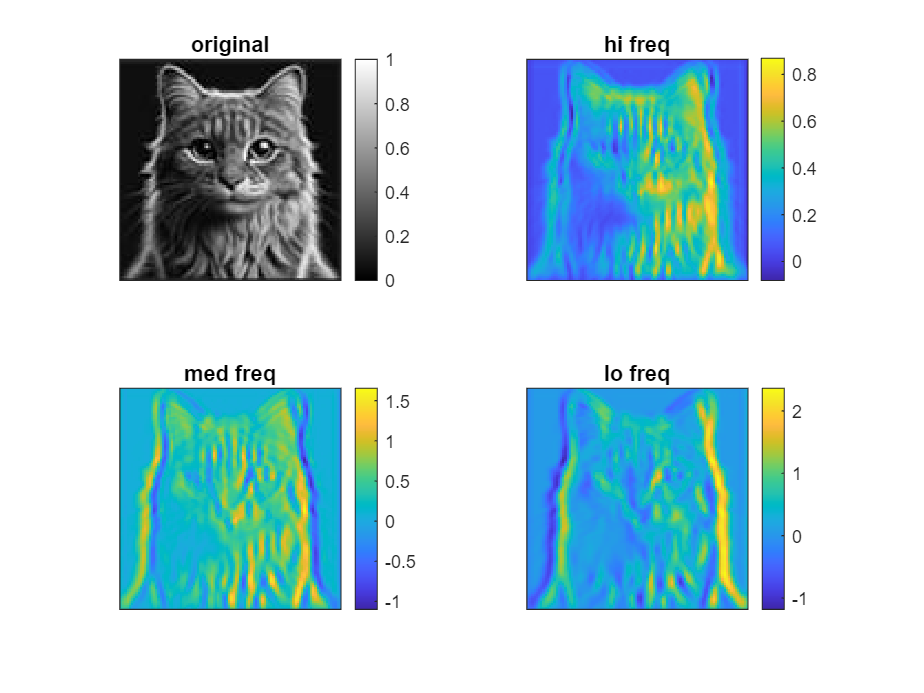

clf;

hifreq=[ -1 -1 -1 +1 +1 -1 -1 ; ...
         -1 -1 -1 +1 +1 -1 -1 ; ...
         -1 -1 -1 +1 +1 -1 -1 ; ...
         -1 -1 -1 +1 +1 -1 -1 ; ...
         -1 -1 -1 +1 +1 -1 -1 ; ...
         -1 -1 -1 +1 +1 -1 -1 ; ...
         -1 -1 -1 +1 +1 -1 -1 ];

medfreq=[-1 -1 -1 +1 +1 +1 -1 ; ...
         -1 -1 -1 +1 +1 +1 -1 ; ...
         -1 -1 -1 +1 +1 +1 -1 ; ...
         -1 -1 -1 +1 +1 +1 -1 ; ...
         -1 -1 -1 +1 +1 +1 -1 ; ...
         -1 -1 -1 +1 +1 +1 -1 ; ...
         -1 -1 -1 +1 +1 +1 -1 ];

lofreq=[ -1 -1 -1 +1 +1 +1 +1 ; ...
         -1 -1 -1 +1 +1 +1 +1 ; ...
         -1 -1 -1 +1 +1 +1 +1 ; ...
         -1 -1 -1 +1 +1 +1 +1 ; ...
         -1 -1 -1 +1 +1 +1 +1 ; ...
         -1 -1 -1 +1 +1 +1 +1 ; ...
         -1 -1 -1 +1 +1 +1 +1 ];

%plot source image
ax1=subplot(2,2,1);
imagesc(noblecat);
axis square; colormap(ax1,'gray'); colorbar; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('original');

% high spatial frequency kernel
ax2=subplot(2,2,2);
kernel=hifreq/sum(hifreq(:)); %normalize sum of weights to be 1
convcat1=conv2(double(noblecat),kernel,'same');
imagesc(convcat1);
axis square; colormap(ax2,'parula'); colorbar; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('hi freq')

% medium spatial frequency kernel
ax3=subplot(2,2,3);
kernel=medfreq/sum(medfreq(:)); %normalize sum of weights to be 1
convcat2=conv2(double(noblecat),kernel,'same');
imagesc(convcat2);
axis square; colormap(ax3,'parula'); colorbar; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('med freq');

% low spatial frequency kernel
ax4=subplot(2,2,4);
kernel=lofreq/sum(lofreq(:)); %normalize sum of weights to be 1
convcat3=conv2(double(noblecat),kernel,'same');
imagesc(convcat3);
axis square; colormap(ax4,'parula'); colorbar; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('lo freq');

Notice that the original input image has only positive pixel values (0 through 1, plotted as grayscale). However, since the edge detection kernels contain both positive and negative weights, the convolution output can contain both positive and negative pixels (plotted using the yellow/blue colormap). In section 4 below, we shall see how a nonlinear activation function can threshold the convolution output so that it only contains positive values. 

## QUESTION 3

The code below below assigns a 7x7 kernel to have all weights set equal to zero. Try to set the 49 weights values so that convolution produces the following result:

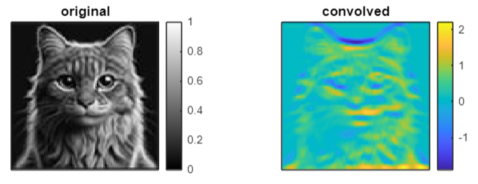

Keep adjusting the weights and hitting 'Run Section' until you get the desired result.

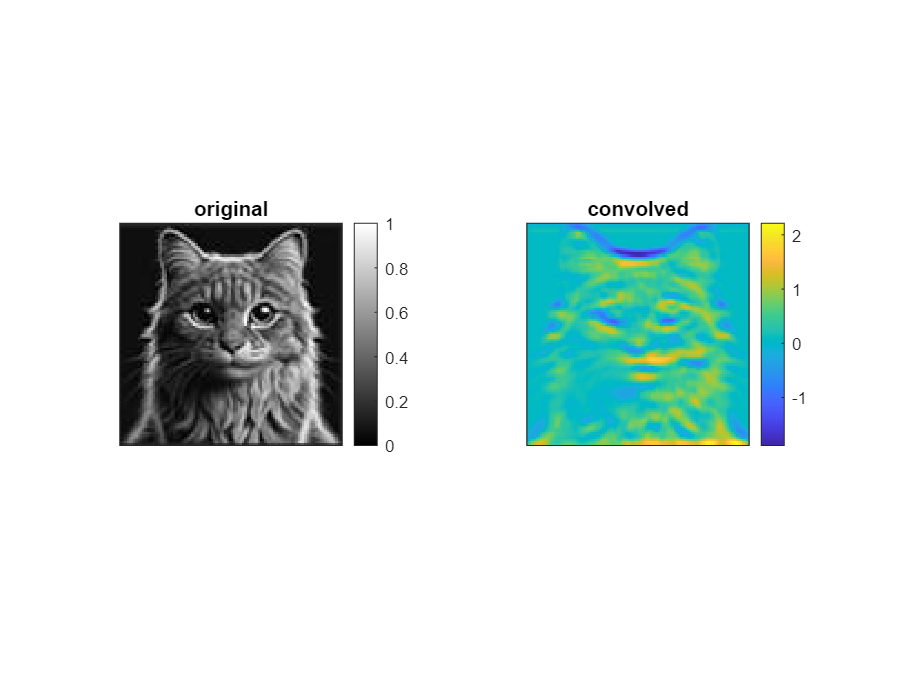

clf;

answer.Q3  =[ -1 -1 -1 -1 -1 -1 -1 ; ...
              -1 -1 -1 -1 -1 -1 -1; ...
              -1 -1 -1 -1 -1 -1 -1; ...
              1 1 1 1 1 1 1; ...
              1 1 1 1 1 1 1; ...
              1 1 1 1 1 1 1; ...
              1 1 1 1 1 1 1];

clf;
kernel=answer.Q3;

%plot source image
ax1=subplot(1,2,1);
imagesc(noblecat);
axis square; colormap(ax1,'gray'); colorbar; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('original');

% plot convolved image
ax2=subplot(1,2,2);
kernel=kernel/sum(kernel(:)); %normalize sum of weights to be 1
convcat=conv2(double(noblecat),kernel,'same');
imagesc(convcat);
axis square; colormap(ax2,'parula'); colorbar; %make plot square, set color range  
set(gca,'XTick',[],'YTick',[]); %remove tick labels
title('convolved');

## SECTION 4: Thresholding: Bias and ReLu

If we pass the convolved image through a ReLu function, then all negative values will be set to zero:

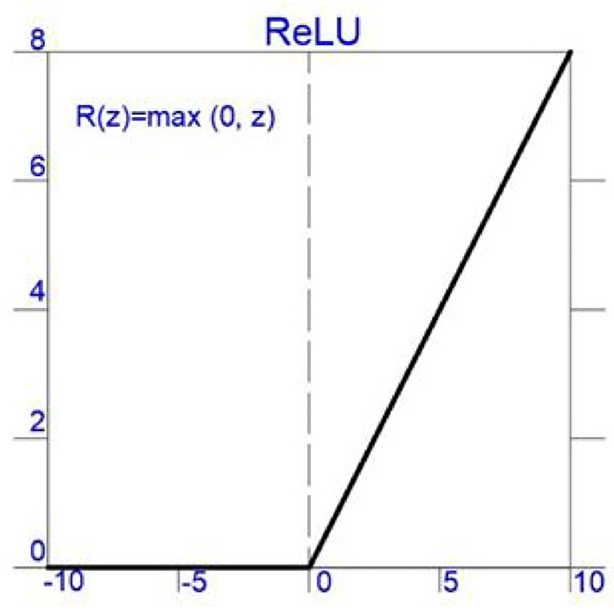

The ReLu function sets a threshold at zero; value less than zero do not pass through, values greater than zero do pass through.

What if we want to set the threshold at a value higher then zero? We can do this by adjusting the value of the bias term for feature map units. The ReLu function then effectively becomes:

R(z+*b*) = max(0,z+*b*)

where *b* is the bias term. A negative bias value sets the output threshold at a value greater than zero, whereas a positive bias value sets the output threshold at a value less than zero. For example *b*=-.5 sets the threshold at +.5 and vice versa. 

Use the slider below to adjust the bias term. 

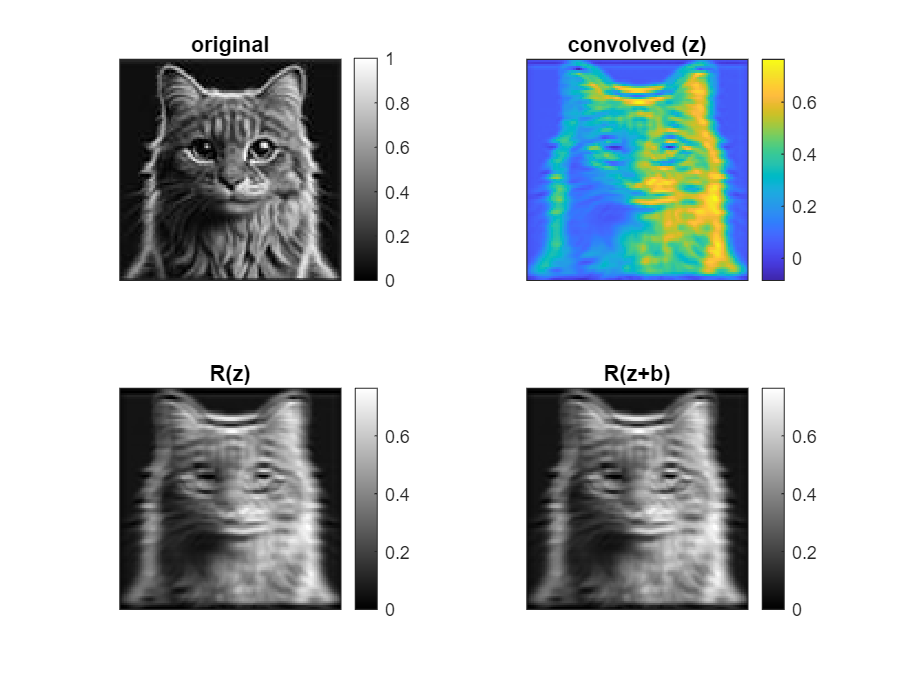

bias=0;

kernel=[ -1 -1 -1 -1 -1 -1 -1 ; ...
         -1 -1 -1 -1 -1 -1 -1 ; ...
         -1 -1 -1 -1 -1 -1 -1 ; ...
         +1 +1 +1 +1 +1 +1 +1 ; ...
         +1 +1 +1 +1 +1 +1 +1 ; ...
         -1 -1 -1 -1 -1 -1 -1 ; ...
         -1 -1 -1 -1 -1 -1 -1 ];
kernel=kernel/sum(kernel(:)); convcat=conv2(double(noblecat),kernel,'same'); 
biascat=convcat+bias; biascat(find(biascat<0))=0; % apply ReLu function to all pixels of the convolved image
clf; ax1=subplot(2,2,1); imagesc(noblecat); axis square; colormap(ax1,'gray'); colorbar; set(gca,'XTick',[],'YTick',[]); title('original'); %plot source image
ax2=subplot(2,2,2); kernel=kernel/sum(kernel(:)); imagesc(convcat); axis square; colormap(ax2,'parula'); colorbar; set(gca,'XTick',[],'YTick',[]); title('convolved (z)'); % plot convolved image
ax3=subplot(2,2,3); relucat=convcat; relucat(find(relucat<0))=0; imagesc(relucat); axis square; colormap(ax3,'gray'); colorbar; set(gca,'XTick',[],'YTick',[]); title('R(z)'); % plot convolved+thresholded image
ax4=subplot(2,2,4); imagesc(biascat); axis square; colormap(ax4,'gray'); colorbar; set(gca,'XTick',[],'YTick',[]); title('R(z+b)'); % use buas term to adjust threshold

## QUESTION 4

Now, in the code below, try to set the bias term (using the slider) and the kernel weights (by entering them in the 7x7 matrix) so that they produce the following results:  

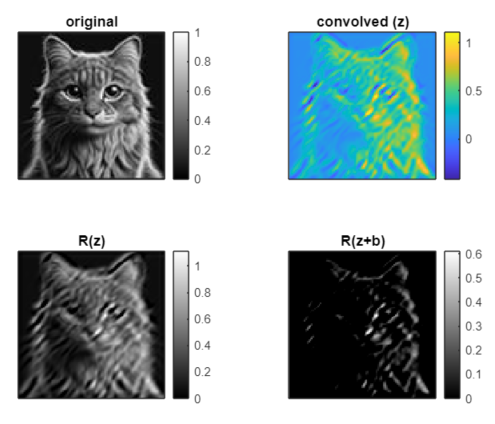

You can check the results for your current selection by clicking 'Run Section.' When you are done move on to the next section to finish the assignment. 

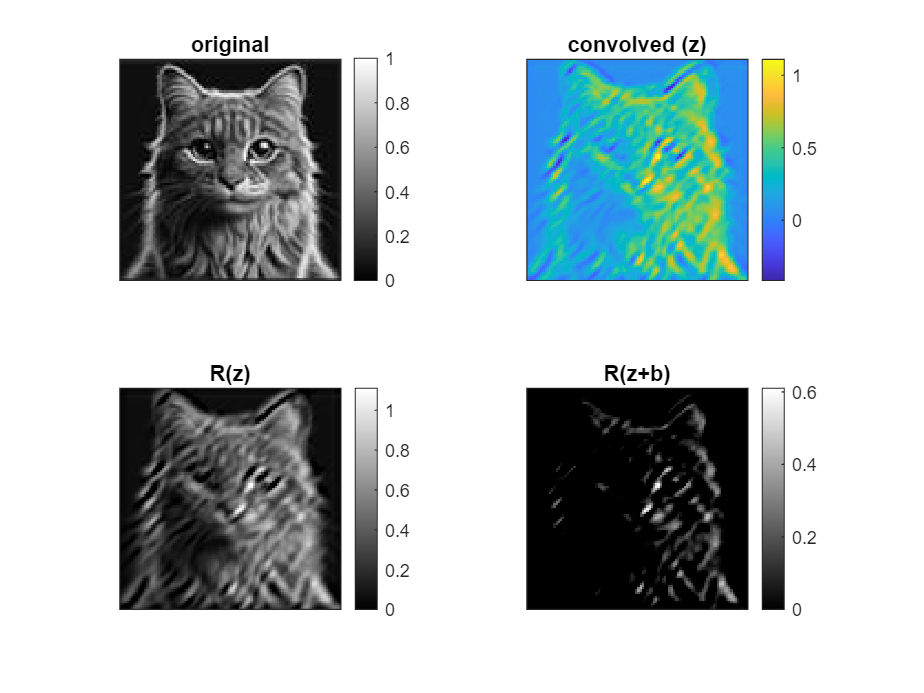

answer.Q4_1=-0.5;

answer.Q4_2=[ -1 -1 -1 -1 -1 +1 +1 ; ...
              -1 -1 -1 -1 +1 +1 +1 ; ...
              -1 -1 -1 +1 +1 +1 -1 ; ...
              -1 -1 +1 +1 +1 -1 -1 ; ...
              -1 +1 +1 +1 -1 -1 -1 ; ...
              +1 +1 +1 -1 -1 -1 -1 ; ...
              +1 +1 -1 -1 -1 -1 -1 ];
kernel=answer.Q4_2/sum(answer.Q4_2(:)); %normalize sum of weights to be 1
convcatf=conv2(double(noblecat),kernel,'same');
biascatf=convcatf+answer.Q4_1; % copy convcat to relucat
biascatf(find(biascatf<0))=0; % apply ReLu function to all pixels of the convolved image
clf; ax1=subplot(2,2,1); imagesc(noblecat); axis square; colormap(ax1,'gray'); colorbar; set(gca,'XTick',[],'YTick',[]); title('original'); %plot source image
ax2=subplot(2,2,2); imagesc(convcatf); axis square; colormap(ax2,'parula'); colorbar; set(gca,'XTick',[],'YTick',[]); title('convolved (z)'); % plot convolved image
ax3=subplot(2,2,3); relucatf=convcatf; relucatf(find(relucatf<0))=0; imagesc(relucatf); axis square; colormap(ax3,'gray'); colorbar; set(gca,'XTick',[],'YTick',[]); title('R(z)'); % plot convolved+thresholded image
ax4=subplot(2,2,4); imagesc(biascatf); axis square; colormap(ax4,'gray'); colorbar; set(gca,'XTick',[],'YTick',[]); title('R(z+b)'); % use buas term to adjust threshold

## SECTION 5: You are done! Submit your work to Canvas

To submit your assignment, follow three steps:

1) run the script below by clicking inside the code window and then hitting 'Run Section' (three graphs will appear below the code)

2) a file called '123456789_assignment3.mat' will be created in your 119D directory (with your SID in place of 123456789)

3) upload this file to Canvas to submit your completed assignment!

%%%SAVE FILE TO SUBMIT ON CANVAS

filename = [num2str(SID) '_assignment4.mat'];
save(['C:\Users\ericy\OneDrive\Desktop\UCLA College stuffs\Senior Class\Winter\PSYCH 119D\MATLAB/' filename],'answer');